syms r1 p2 p3 p4 r5;
syms l1 l2 l3 l4 l5 ltx lty ltz;

MDH = [0 0 -l1 r1;
       0 90 p2 -90;
       l2 -90 p3 -90;
       l3 -90 (l4+p4) -90;
       0 -90 l5 r5;
       ltx -90 -ltz 0];

Ti = @(i) [cosd(MDH(i,4)), -sind(MDH(i,4)), 0, MDH(i,1);
    cosd(MDH(i,2))*sind(MDH(i,4)), cosd(MDH(i,2))*cosd(MDH(i,4)), -sind(MDH(i,2)), -MDH(i,3)*sind(MDH(i,2));
    sind(MDH(i,2))*sind(MDH(i,4)), sind(MDH(i,2))*cosd(MDH(i,4)), cosd(MDH(i,2)), MDH(i,3)*cosd(MDH(i,2));
    0, 0, 0, 1];

T01 = Ti(1);
T12 = Ti(2);
T23 = Ti(3);
T34 = Ti(4);
T45 = Ti(5);
% T5t = Ti(6);
T5t = transl(ltx, -ltz, lty) * trotx(-pi/2);
T05 = T01 * T12 * T23 * T34 * T45;
T0t = T05 * T5t

$$T0t = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\sigma_{4} & -\sigma_{1} & -\sigma_{2}\,\sigma_{3} & p_{3}\,\sigma_{2}+l_{3}\,\sigma_{1}+l_{5}\,\sigma_{1}+\mathrm{lty}\,\sigma_{1}+p_{2}\,\sigma_{1}+\mathrm{ltx}\,\sigma_{2}\,\sigma_{4}+\mathrm{ltz}\,\sigma_{2}\,\sigma_{3}\\ \sigma_{4}\,\sigma_{1} & \sigma_{2} & -\sigma_{1}\,\sigma_{3} & p_{3}\,\sigma_{1}-l_{5}\,\sigma_{2}-\mathrm{lty}\,\sigma_{2}-p_{2}\,\sigma_{2}-l_{3}\,\sigma_{2}+\mathrm{ltx}\,\sigma_{4}\,\sigma_{1}+\mathrm{ltz}\,\sigma_{1}\,\sigma_{3}\\ \sigma_{3} & 0 & \sigma_{4} & \mathrm{ltx}\,\sigma_{3}-l_{2}-l_{4}-p_{4}-\mathrm{ltz}\,\sigma_{4}-l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,r_{5}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,r_{5}}{180}\right) \end{array}$$

syms dx dy dz dry drz

delta = [0 -drz dry dx;
    drz 0 0 dy;
    -dry 0 0 dz;
    0 0 0 0];

T0t * delta

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \mathrm{dry}\,\sigma_{4}\,\sigma_{2}-\mathrm{drz}\,\sigma_{3} & -\mathrm{drz}\,\sigma_{4}\,\sigma_{1} & \mathrm{dry}\,\sigma_{4}\,\sigma_{1} & \mathrm{dx}\,\sigma_{4}\,\sigma_{1}-\mathrm{dy}\,\sigma_{3}-\mathrm{dz}\,\sigma_{4}\,\sigma_{2}\\ \mathrm{drz}\,\sigma_{4}+\mathrm{dry}\,\sigma_{3}\,\sigma_{2} & -\mathrm{drz}\,\sigma_{1}\,\sigma_{3} & \mathrm{dry}\,\sigma_{1}\,\sigma_{3} & \mathrm{dy}\,\sigma_{4}+\mathrm{dx}\,\sigma_{1}\,\sigma_{3}-\mathrm{dz}\,\sigma_{3}\,\sigma_{2}\\ -\mathrm{dry}\,\sigma_{1} & -\mathrm{drz}\,\sigma_{2} & \mathrm{dry}\,\sigma_{2} & \mathrm{dz}\,\sigma_{1}+\mathrm{dx}\,\sigma_{2}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,r_{5}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,r_{5}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,r_{1}}{180}\right) \end{array}$$

deltaR = [0 dry drz]

$$deltaR = \left(\begin{array}{ccc} 0 & \mathrm{dry} & \mathrm{drz} \end{array}\right)$$

delta = [dx dy dz]

$$delta = \left(\begin{array}{ccc} \mathrm{dx} & \mathrm{dy} & \mathrm{dz} \end{array}\right)$$

tdrx = dot(deltaR, T0t(1, 1:3))

$$tdrx = -\sin\left(\frac{\pi \,r_{1}}{180}\right)\,\bar{\mathrm{dry}}-\cos\left(\frac{\pi \,r_{1}}{180}\right)\,\sin\left(\frac{\pi \,r_{5}}{180}\right)\,\bar{\mathrm{drz}}$$

tdry = dot(deltaR, T0t(2, 1:3))

$$tdry = \cos\left(\frac{\pi \,r_{1}}{180}\right)\,\bar{\mathrm{dry}}-\sin\left(\frac{\pi \,r_{1}}{180}\right)\,\sin\left(\frac{\pi \,r_{5}}{180}\right)\,\bar{\mathrm{drz}}$$

tdrz = dot(deltaR, T0t(3, 1:3))

$$tdrz = \cos\left(\frac{\pi \,r_{5}}{180}\right)\,\bar{\mathrm{drz}}$$

tdx = dot(T0t(1, 1:3), (cross(deltaR, T0t(1:3, 4)') + delta))

$$tdx = \begin{array}{l} \sigma_{2}\,\sigma_{5}\,\left(\mathrm{dx}-\mathrm{dry}\,\left(\bar{l_{1}}+\bar{l_{2}}+\bar{l_{4}}+\bar{p_{4}}+\bar{\mathrm{ltz}}\,\sigma_{5}-\bar{\mathrm{ltx}}\,\sigma_{4}\right)+\mathrm{drz}\,\left(\bar{l_{3}}\,\sigma_{2}+\bar{l_{5}}\,\sigma_{2}+\bar{\mathrm{lty}}\,\sigma_{2}+\bar{p_{2}}\,\sigma_{2}-\bar{p_{3}}\,\sigma_{3}-\bar{\mathrm{ltx}}\,\sigma_{5}\,\sigma_{3}-\bar{\mathrm{ltz}}\,\sigma_{3}\,\sigma_{4}\right)\right)-\sigma_{3}\,\left(\mathrm{dy}+\mathrm{drz}\,\sigma_{1}\right)-\sigma_{2}\,\sigma_{4}\,\left(\mathrm{dz}-\mathrm{dry}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{p_{3}}\,\sigma_{2}+\bar{l_{3}}\,\sigma_{3}+\bar{l_{5}}\,\sigma_{3}+\bar{\mathrm{lty}}\,\sigma_{3}+\bar{p_{2}}\,\sigma_{3}+\bar{\mathrm{ltx}}\,\sigma_{2}\,\sigma_{5}+\bar{\mathrm{ltz}}\,\sigma_{2}\,\sigma_{4}\\ \sigma_{2}=\cos\left(\frac{\pi \,\bar{r_{1}}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,\bar{r_{1}}}{180}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\bar{r_{5}}}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,\bar{r_{5}}}{180}\right) \end{array}$$

tdy = dot(T0t(2, 1:3), (cross(deltaR, T0t(1:3, 4)') + delta))

$$tdy = \begin{array}{l} \sigma_{3}\,\left(\mathrm{dy}+\mathrm{drz}\,\sigma_{1}\right)-\sigma_{2}\,\sigma_{4}\,\left(\mathrm{dz}-\mathrm{dry}\,\sigma_{1}\right)+\sigma_{5}\,\sigma_{2}\,\left(\mathrm{dx}-\mathrm{dry}\,\left(\bar{l_{1}}+\bar{l_{2}}+\bar{l_{4}}+\bar{p_{4}}+\bar{\mathrm{ltz}}\,\sigma_{5}-\bar{\mathrm{ltx}}\,\sigma_{4}\right)+\mathrm{drz}\,\left(\bar{l_{3}}\,\sigma_{3}+\bar{l_{5}}\,\sigma_{3}+\bar{\mathrm{lty}}\,\sigma_{3}+\bar{p_{2}}\,\sigma_{3}-\bar{p_{3}}\,\sigma_{2}-\bar{\mathrm{ltx}}\,\sigma_{5}\,\sigma_{2}-\bar{\mathrm{ltz}}\,\sigma_{2}\,\sigma_{4}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{p_{3}}\,\sigma_{3}+\bar{l_{3}}\,\sigma_{2}+\bar{l_{5}}\,\sigma_{2}+\bar{\mathrm{lty}}\,\sigma_{2}+\bar{p_{2}}\,\sigma_{2}+\bar{\mathrm{ltx}}\,\sigma_{3}\,\sigma_{5}+\bar{\mathrm{ltz}}\,\sigma_{3}\,\sigma_{4}\\ \sigma_{2}=\sin\left(\frac{\pi \,\bar{r_{1}}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\bar{r_{1}}}{180}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\bar{r_{5}}}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,\bar{r_{5}}}{180}\right) \end{array}$$

tdz = dot(T0t(3, 1:3), (cross(deltaR, T0t(1:3, 4)') + delta))

$$tdz = \begin{array}{l} \sin\left(\sigma_{1}\right)\,\left(\mathrm{dx}-\mathrm{dry}\,\left(\bar{l_{1}}+\bar{l_{2}}+\bar{l_{4}}+\bar{p_{4}}+\bar{\mathrm{ltz}}\,\cos\left(\sigma_{1}\right)-\bar{\mathrm{ltx}}\,\sin\left(\sigma_{1}\right)\right)+\mathrm{drz}\,\left(\bar{l_{3}}\,\cos\left(\sigma_{2}\right)+\bar{l_{5}}\,\cos\left(\sigma_{2}\right)+\bar{\mathrm{lty}}\,\cos\left(\sigma_{2}\right)+\bar{p_{2}}\,\cos\left(\sigma_{2}\right)-\bar{p_{3}}\,\sin\left(\sigma_{2}\right)-\bar{\mathrm{ltx}}\,\cos\left(\sigma_{1}\right)\,\sin\left(\sigma_{2}\right)-\bar{\mathrm{ltz}}\,\sin\left(\sigma_{2}\right)\,\sin\left(\sigma_{1}\right)\right)\right)+\cos\left(\sigma_{1}\right)\,\left(\mathrm{dz}-\mathrm{dry}\,\left(\bar{p_{3}}\,\cos\left(\sigma_{2}\right)+\bar{l_{3}}\,\sin\left(\sigma_{2}\right)+\bar{l_{5}}\,\sin\left(\sigma_{2}\right)+\bar{\mathrm{lty}}\,\sin\left(\sigma_{2}\right)+\bar{p_{2}}\,\sin\left(\sigma_{2}\right)+\bar{\mathrm{ltx}}\,\cos\left(\sigma_{2}\right)\,\cos\left(\sigma_{1}\right)+\bar{\mathrm{ltz}}\,\cos\left(\sigma_{2}\right)\,\sin\left(\sigma_{1}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\bar{r_{5}}}{180}\\ \sigma_{2}=\frac{\pi \,\bar{r_{1}}}{180} \end{array}$$

r1 = 0;
p2 = 0;
p3 = 0;
p4 = 0;
r5 = 0;
T0t0 = eval(T0t)

T0t0 =     1.0000         0         0   67.9000
         0    1.0000         0  -35.3500
         0         0    1.0000 -105.2500
         0         0         0    1.0000


% eval(T01)
% eval(T12)
% eval(T23)
% eval(T34)
% eval(T45)
% eval(T5t)
% eval(T01 * T12 * T23 * T34 * T45 * T5t)

syms ry rz px py pz
Tt0t = [cos(rz)*cos(ry), -sin(rz), cos(rz)*sin(ry), px;
    sin(rz)*cos(ry), cos(rz), sin(rz)*sin(ry), py;
    -sin(ry), 0, cos(ry), pz;
    0, 0, 0, 1]

$$Tt0t = \left(\begin{array}{cccc} \cos\left(\mathrm{ry}\right)\,\cos\left(\mathrm{rz}\right) & -\sin\left(\mathrm{rz}\right) & \cos\left(\mathrm{rz}\right)\,\sin\left(\mathrm{ry}\right) & \mathrm{px}\\ \cos\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right) & \cos\left(\mathrm{rz}\right) & \sin\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right) & \mathrm{py}\\ -\sin\left(\mathrm{ry}\right) & 0 & \cos\left(\mathrm{ry}\right) & \mathrm{pz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0t0 * Tt0t / T5t

$$ans = \left(\begin{array}{cccc} \cos\left(\mathrm{ry}\right)\,\cos\left(\mathrm{rz}\right) & \cos\left(\mathrm{rz}\right)\,\sin\left(\mathrm{ry}\right) & \sin\left(\mathrm{rz}\right) & \mathrm{px}-\frac{679\,\cos\left(\mathrm{ry}\right)\,\cos\left(\mathrm{rz}\right)}{10}+\frac{111\,\cos\left(\mathrm{rz}\right)\,\sin\left(\mathrm{ry}\right)}{4}+\frac{679}{10}\\ \cos\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right) & \sin\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right) & -\cos\left(\mathrm{rz}\right) & \mathrm{py}-\frac{679\,\cos\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right)}{10}+\frac{111\,\sin\left(\mathrm{ry}\right)\,\sin\left(\mathrm{rz}\right)}{4}-\frac{707}{20}\\ -\sin\left(\mathrm{ry}\right) & \cos\left(\mathrm{ry}\right) & 0 & \mathrm{pz}+\frac{111\,\cos\left(\mathrm{ry}\right)}{4}+\frac{679\,\sin\left(\mathrm{ry}\right)}{10}-\frac{421}{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T05

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\sigma_{4} & -\sigma_{2}\,\sigma_{3} & \sigma_{1} & \frac{707\,\sigma_{1}}{20}+p_{3}\,\sigma_{2}+p_{2}\,\sigma_{1}\\ \sigma_{4}\,\sigma_{1} & -\sigma_{1}\,\sigma_{3} & -\sigma_{2} & p_{3}\,\sigma_{1}-p_{2}\,\sigma_{2}-\frac{707\,\sigma_{2}}{20}\\ \sigma_{3} & \sigma_{4} & 0 & -p_{4}-\frac{155}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,r_{5}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,r_{5}}{180}\right) \end{array}$$

T0t0

T0t0 =     1.0000         0         0   67.9000
         0    1.0000         0  -35.3500
         0         0    1.0000 -105.2500
         0         0         0    1.0000


T5t

$$T5t = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{679}{10}\\ 0 & 0 & 1 & -\frac{111}{4}\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

inv(T5t)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -\frac{679}{10}\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & \frac{111}{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%到末端法兰的运动学
[px, py, pz, ry, rz] = D5R_FwKine(0,0,0,0,0)

px = 0

py = -35.3500

pz = -77.5000

ry = 0

rz = 0

[j1, j2, j3, j4, j5] = D5R_InvKine(px, py, pz, ry, rz)

j1 = 0

j2 = 0

j3 = 0

j4 = 0

j5 = 0

syms ltx lty ltz
T5t = [1, 0, 0, ltx;
       0, 0, 1, -ltz;
       0, -1, 0, lty;
       0, 0, 0, 1];
T0t = T05 * T5t

$$T0t = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\sigma_{4} & -\sigma_{1} & -\sigma_{2}\,\sigma_{3} & \frac{707\,\sigma_{1}}{20}+p_{3}\,\sigma_{2}+\mathrm{lty}\,\sigma_{1}+p_{2}\,\sigma_{1}+\mathrm{ltx}\,\sigma_{2}\,\sigma_{4}+\mathrm{ltz}\,\sigma_{2}\,\sigma_{3}\\ \sigma_{4}\,\sigma_{1} & \sigma_{2} & -\sigma_{1}\,\sigma_{3} & p_{3}\,\sigma_{1}-\mathrm{lty}\,\sigma_{2}-p_{2}\,\sigma_{2}-\frac{707\,\sigma_{2}}{20}+\mathrm{ltx}\,\sigma_{4}\,\sigma_{1}+\mathrm{ltz}\,\sigma_{1}\,\sigma_{3}\\ \sigma_{3} & 0 & \sigma_{4} & \mathrm{ltx}\,\sigma_{3}-\mathrm{ltz}\,\sigma_{4}-p_{4}-\frac{155}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,r_{1}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,r_{5}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,r_{5}}{180}\right) \end{array}$$

%到工具端的运动学
l1 = 38;
l2 = 11.5;
l3 = 17.25;
l4 = 28;
l5 = 18.1;
[x,y,z,ry,rz] = D5RTool_FwKine(0,0,0,0,0)

x = 67.9000

y = -76.8500

z = -105.2500

ry = 0

rz = 0

% eval([x,y,z,ry,rz])
[j1,j2,j3,j4,j5] = D5RTool_InvKine(x,y,z,ry,rz)

j1 = 0

$$j2 = \frac{1537}{20}-l_{5}-\mathrm{lty}-l_{3}$$

$$j3 = \frac{679}{10}-\mathrm{ltx}$$

$$j4 = \frac{421}{4}-l_{2}-l_{4}-\mathrm{ltz}-l_{1}$$

j5 = 0

% [j1,j2,j3,j4,j5] = D5RTool_InvKine(x,y,z,ry,rz+90)

% 用蒙特卡洛方法分析可达工作空间
N = 1000;

l1 = 38;
l2 = 11.5;
l3 = 17.25;
l4 = 28;
l5 = 18.1;
ltx = 67.9;
lty = 41.5;
ltz = 27.75;
% lim1_min = -90;
% lim1_max = 90;
% lim2_min = -10;
% lim2_max = 10;
% lim3_min = -10;
% lim3_max = -10;
% lim4_min = -10;
% lim4_max = -10;
% lim5_min = 90;
% lim5_max = -90;
% lim1_range = lim1_max - lim1_min;
% lim2_range = lim2_max - lim1_min;
% lim1_range = lim1_max - lim1_min;
% lim1_range = lim1_max - lim1_min;
% lim1_range = lim1_max - lim1_min;

Limit = [-90 90 180;
         -10 10 20;
         -10 10 20;
         -10 10 20;
         -90 90 180];

% J1 = Limit(1,1) + Limit(1,3) .* rand(N,1); 
% J2 = Limit(2,1) + Limit(2,3) .* rand(N,1);
Joints = zeros(N,5);
for i=1:5
    Joints(:,i) = Limit(i,1) + Limit(i,3) .* rand(N,1);
end

[X,Y,Z] = D5RTool_FwKine(Joints(:,1), Joints(:,2), Joints(:,3), Joints(:,4), Joints(:,5));


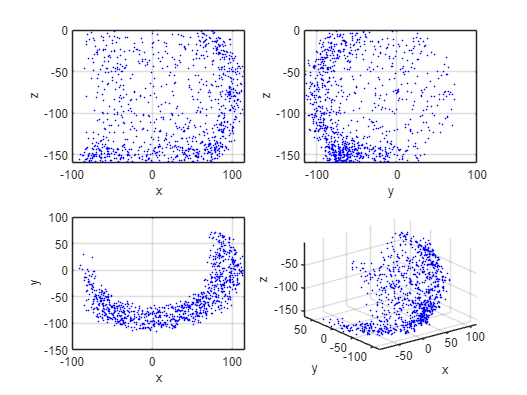

% 画图
for n=1:N
    % [x,y,z] = D5RTool_FwKine(Joints(n,1),Joints(n,2),Joints(n,3), Joints(n,4), Joints(n,5));
    % x = eval(x);
    % y = eval(y);
    % z = eval(z);
    x = X(n);
    y = Y(n);
    z = Z(n);

    subplot(2,2,1);
    plot(x,z,'b.','markersize',1);
    xlabel('x');
    ylabel('z');
    grid on;
    hold on;

    subplot(2,2,2);
    plot(y,z,'b.','markersize',1);
    xlabel('y');
    ylabel('z');
    grid on;
    hold on;

    subplot(2,2,3);
    plot(x,y,'b.','markersize',1);
    xlabel('x');
    ylabel('y');
    grid on;
    hold on;

    subplot(2,2,4);
    plot3(x,y,z,'b.','markersize',1);
    xlabel('x');
    ylabel('y');
    zlabel('z');
    grid on;
    hold on;
end

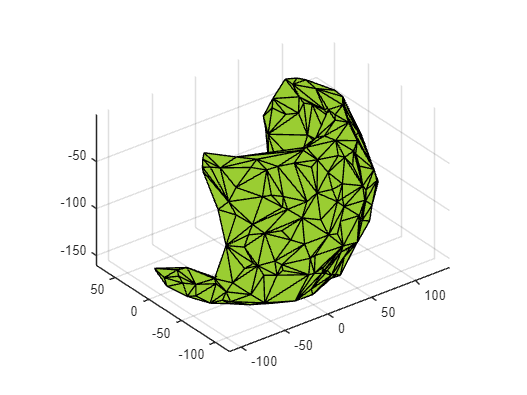

% 用 alpha shape 边界分析

shp_xz = alphaShape(X,Z,20);
shp_yz = alphaShape(Y,Z,20);
shp_xy = alphaShape(X,Y,20);
shp_xyz = alphaShape(X,Y,Z,50);

clf;
plot(shp_xyz);

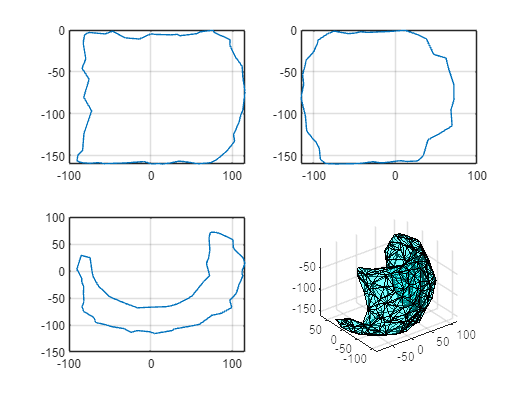


[bf_xz,bd_xz] = boundaryFacets(shp_xz);
[bf_yz,bd_yz] = boundaryFacets(shp_yz);
[bf_xy,bd_xy] = boundaryFacets(shp_xy);
[bf_xyz,bd_xyz] = boundaryFacets(shp_xyz);

clf;
subplot(2,2,1);
% plot(shp_xz);
bd_xz = [bd_xz;bd_xz(1,:)];
plot(bd_xz(:,1),bd_xz(:,2));
grid on;
subplot(2,2,2);
% plot(shp_yz);
bd_yz = [bd_yz;bd_yz(1,:)];
plot(bd_yz(:,1),bd_yz(:,2));
grid on;
subplot(2,2,3);
% plot(shp_xy);
bd_xy = [bd_xy;bd_xy(1,:)];
plot(bd_xy(:,1),bd_xy(:,2));
grid on;
subplot(2,2,4);
trisurf(bf_xyz,bd_xyz(:,1),bd_xyz(:,2),bd_xyz(:,3),...
    'FaceColor','cyan','FaceAlpha',0.3)
axis equal